# Comparison of closed-loop responses with different compensators

This file compares the closed-loop responses for a single system *G(s)* associated to multiple different compensators. The user can define these compensators, and the number of compensators, in an obvious manner. The file uses cell arrays and loops to improve efficiency of coding so scaling is very quick (add one line only to add another compensator).

We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx, closed_vs_openloop_overlay.mlx ***and ***step_responses_with_matlab.mlx.***

This live script needs the control toolbox.

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Enter the examples

- Plotting of closed-loop behaviour

## 1. Technical and mathematical background

Assume the following simple feedback loop.

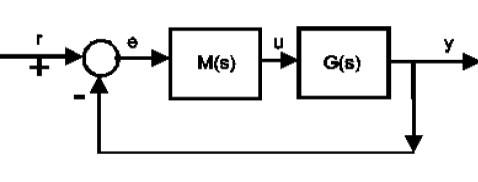

Using a standard feedback loop we have:

$Y\left(s\right)=G_c \left(s\right)R\left(s\right)$ with   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$

$U\left(s\right)=G_{\textrm{cu}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{cu}} =\frac{M}{1+\textrm{GM}}$

$E\left(s\right)=G_{\textrm{ce}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$

The code below will generate all the transfer functions and then the corresponding step responses before creating the plots manually to ensure these are clear and easy to read.

- Section 1 creates the closed-loop transfer functions for each compensator and associated step responses.

- Section 2 produces the plots overlaying the step responses (outputs, inputs).

To run a different example, change the data in section 1 and re-run the whole file.

## 2. Enter the examples 

Note that the compensators and closed-loop transfer functions are stored in cell arrays and a loop is used based on how many compensators are defined. The example code creates 5 compensators but you can have more or less as required.

The default uses the following numbers. Modify the code below for different examples.

$G\left(s\right)=\frac{1}{s^2 +5s+6};\;\;\textrm{M1}=1;\;\;\textrm{M2}\left(s\right)=\frac{4}{s}$;  $\textrm{M3}=\frac{6s+8}{s};\textrm{M4}=\frac{6s+8}{s+0\ldotp 4};\textrm{M5}=\frac{3s+4}{s}$

Note: These compensators are not well designed and used for illustration only.

#### Create the system and compensator objects in MATLAB as follows

YOU MUST DEFINE THE DESIRED SIMULATION TIME (see line 1 below).

simulationtime=8;
G=tf(1,[1 5 6])

G =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.



M=cell(1);
M{1}=6;                 % Proportional
M{2}=tf(4,[1 0]);       % Simple integral
M{3}=tf([6,8],[1 0]);   % PI
M{4} = tf([6 8],[1 0.4]); % lag
M{5} = tf([3 4],[1 0]); % lower gain PI
number_compensators = length(M);

#### Create the closed-loop transfer functions for each compensator

time = linspace(1,simulationtime,101);
leg=cell(1); Gc = cell(1); Gcu = cell(1); y = cell(1); u = cell(1);

for k=1:number_compensators

    Gc{k}=feedback(G*M{k},1);  % for output responses
    Gcu{k}=feedback(M{k},G);   % for input responses
    y{k}=step(Gc{k},time);
    u{k}=step(Gcu{k},time);
    leg{k}=['M',num2str(k)];   % define legend

end


disp('END OF SECTION 2')

END OF SECTION 2


## **3. Plotting of closed-loop behaviour**

Here a loop is used to plot/overlay the input and output responses on the same figure.

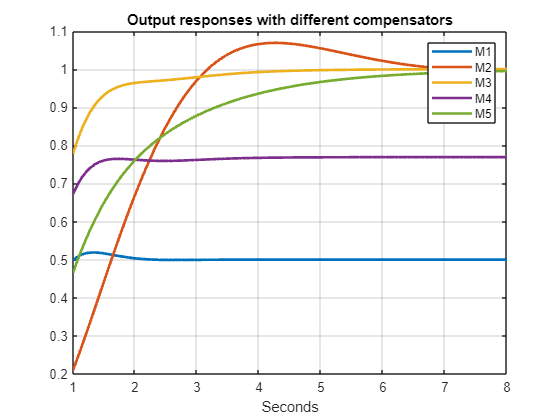

% Code creates outputs and inputs in separate loops for clarity and to enable larger
% figures
figure; clf 
for k=1:number_compensators
    plot(time,y{k},'linewidth',2); 
    hold on
end
grid
legend(leg)
title('Output step responses with different compensators')
xlabel('Seconds')

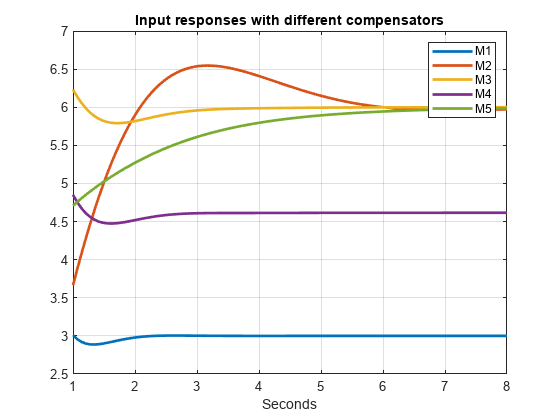


% Input plots below
figure; clf 
for k=1:number_compensators
    plot(time,u{k},'linewidth',2)
    hold on
end
grid
legend(leg)
title('Input step responses with different compensators')
xlabel('Seconds')



disp('END OF SECTION 3')

END OF SECTION 3
